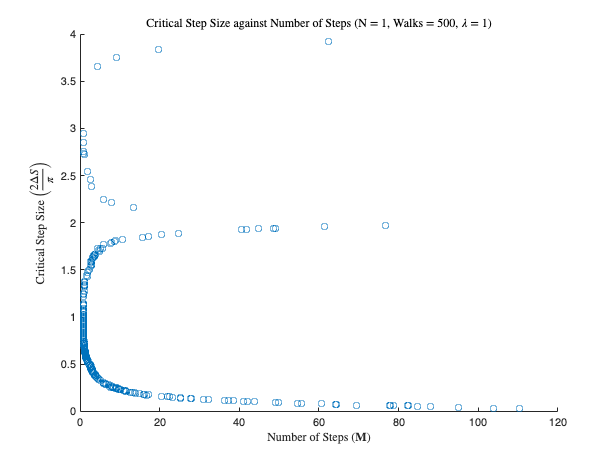

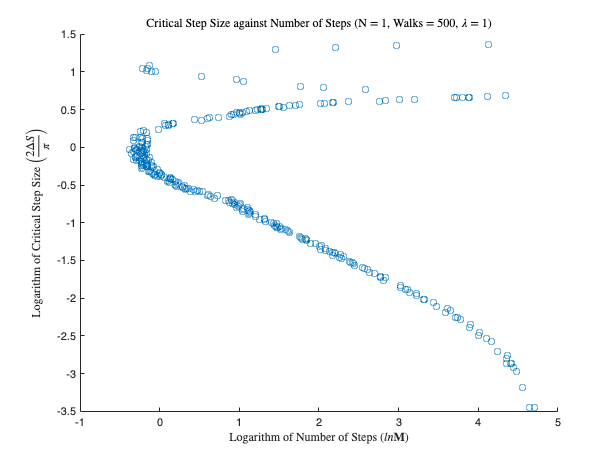

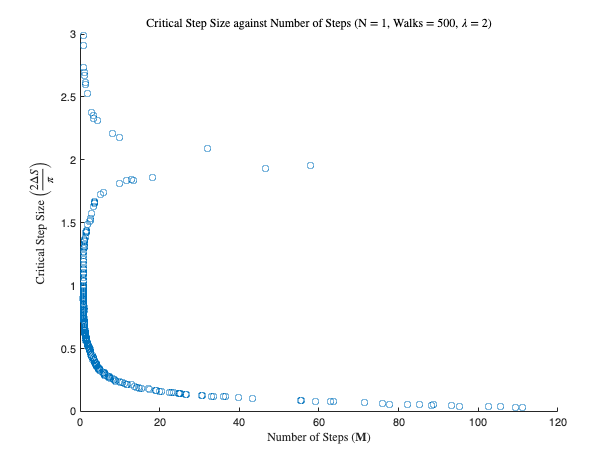

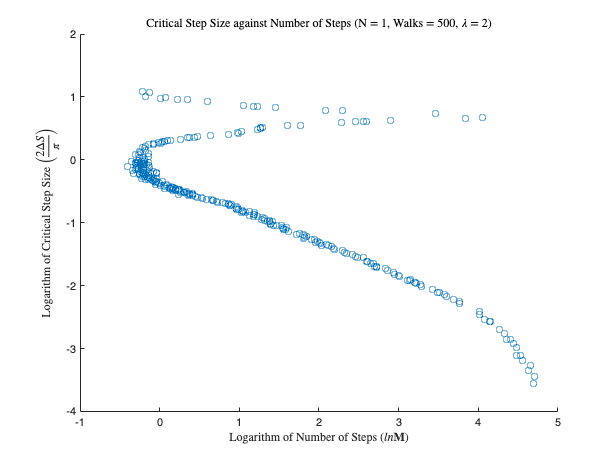

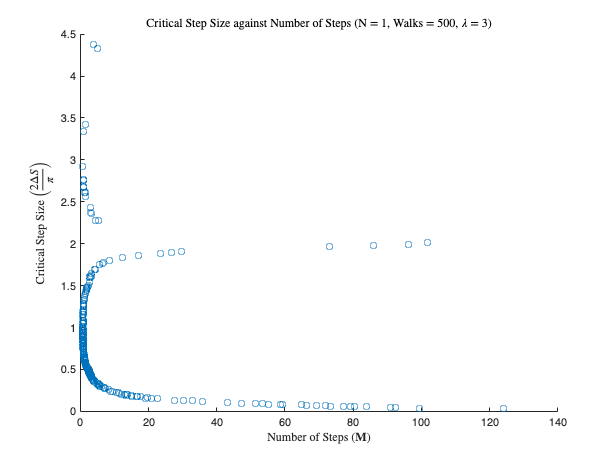

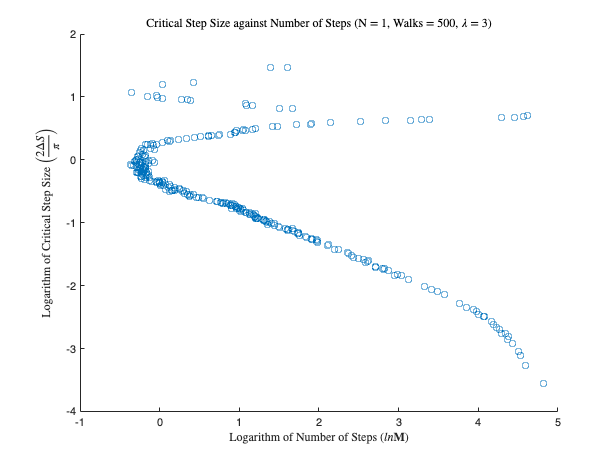

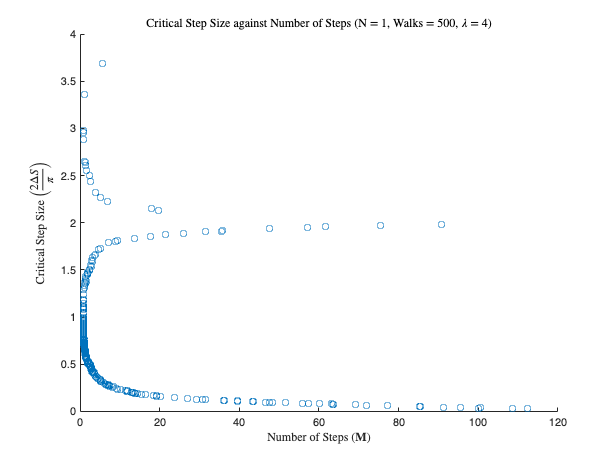

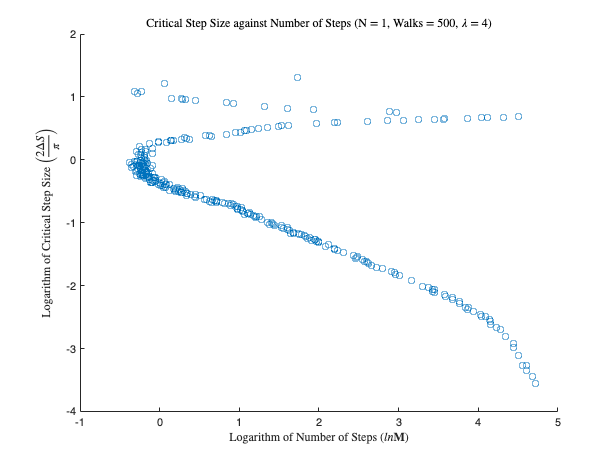

The Simulation has been completed for:
Number of Walks: 500
Number of Steps: 125
For (up to) 1 Qubits


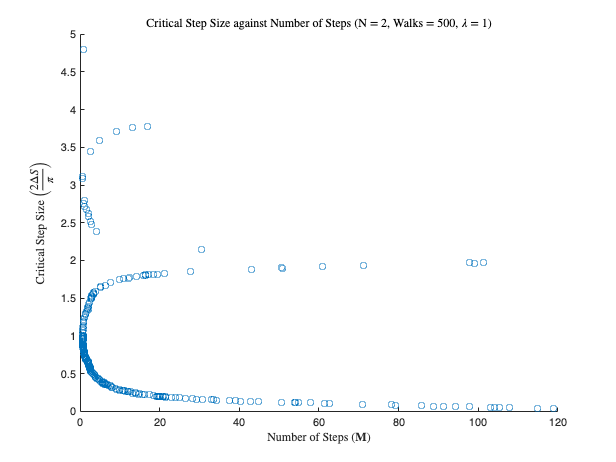

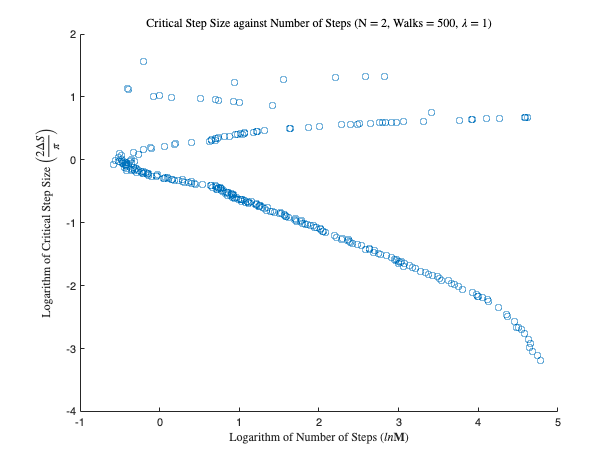

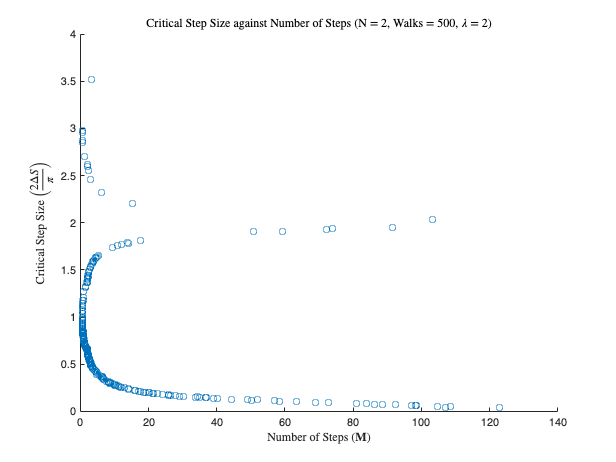

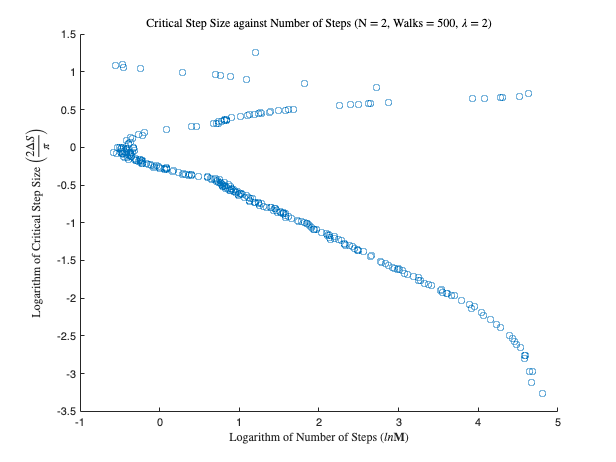

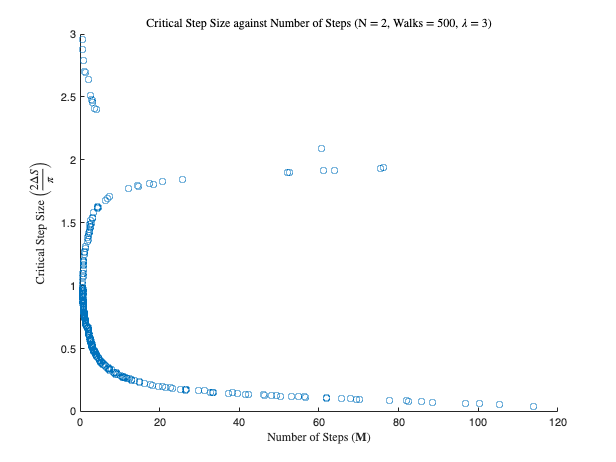

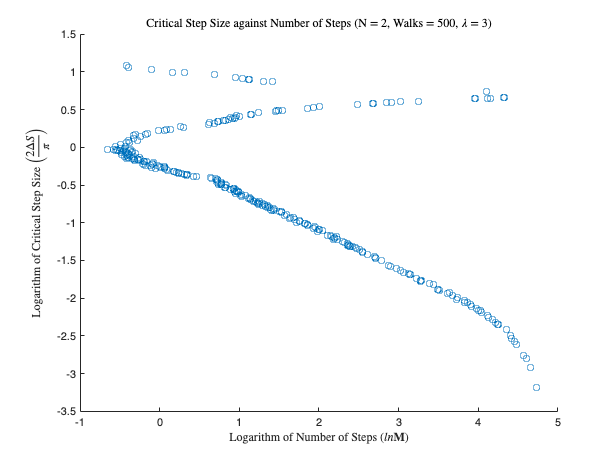

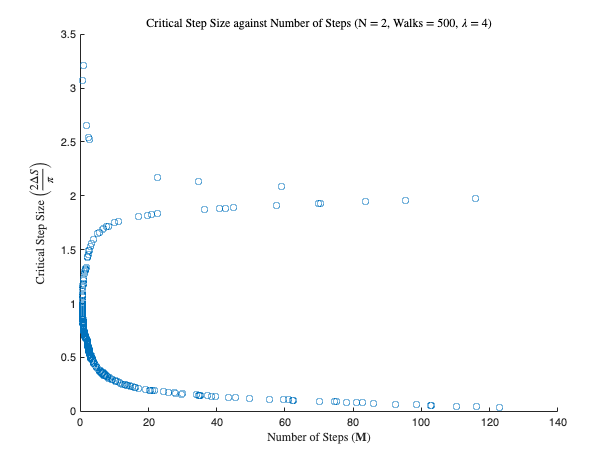

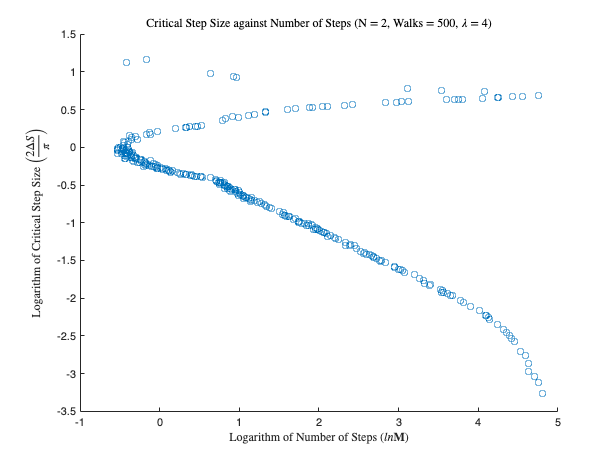

The Simulation has been completed for:
Number of Walks: 500
Number of Steps: 125
For (up to) 2 Qubits


Number_of_Walks = 5e2;
Number_of_Steps = 125;

Maximum_Number_of_Qubits = 2;

Step_Size_Lower_Bound = 0;
Step_Size_Upper_Bound = pi*0.5;
Step_Size_Increment = 5e-3;


Data_Collection_Function(Number_of_Walks, Number_of_Steps, Maximum_Number_of_Qubits, Step_Size_Upper_Bound, Step_Size_Lower_Bound, Step_Size_Increment);



function Data = Data_Collection_Function(Number_of_Walks, ...
                                         Number_of_Steps, ...
                                         Maximum_Number_of_Qubits, ...
                                         Step_Size_Upper_Bound, ...
                                         Step_Size_Lower_Bound, ...
                                         Step_Size_Increment)

    
   
    for Number_of_Qubits = 1:Maximum_Number_of_Qubits
        for Rate = 1:4
            n = 0;
            Data = zeros(2,Number_of_Steps);
            Precision = pi/2 - acos(1/sqrt(2^Number_of_Qubits));
    
                for Step_Size = Step_Size_Lower_Bound:Step_Size_Increment:Step_Size_Upper_Bound
    
                    Step_Size = Step_Size * Poisson_Scaling_Function(1);
                    Results = Random_Walk_Algorithm(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size, Precision);
                    
                    if isempty(Results) == 1 
                        
                    else 
                        n = n+1;
                    
                        Data(:,n) = [(2*Step_Size)/pi ; mean(Results(2,:))];
                    end 
                end
       
                    
                
                    figure;
                    scatter(Data(2,:), Data(1,:));
                    %xlim([3, Number_of_Steps]);
                    xlabel(sprintf('Number of Steps ($\\mathbf{M}$)'), 'Interpreter', 'latex'); 
                    ylabel('Critical Step Size $\left( \frac{ 2 \Delta S }{\pi} \right)$', 'Interpreter', 'latex'); 
                    title(sprintf('Critical Step Size against Number of Steps (N = %d, Walks = %d, $ \\lambda $ = %d)', Number_of_Qubits, Number_of_Walks, Rate), 'Interpreter', 'latex');
                
                    figure;
                    scatter(log(Data(2,:)), log(Data(1,:)));
                    %xlim([1,log(Number_of_Steps)]);
                    xlabel(sprintf('Logarithm of Number of Steps ($ ln\\mathbf{M}$)'), 'Interpreter', 'latex'); 
                    ylabel('Logarithm of Critical Step Size $\left( \frac{ 2 \Delta S }{\pi} \right)$', 'Interpreter', 'latex');  
                    title(sprintf('Critical Step Size against Number of Steps (N = %d, Walks = %d, $ \\lambda $ = %d)', Number_of_Qubits, Number_of_Walks, Rate), 'Interpreter', 'latex');

                       
                    
        end
    
    
        fprintf('The Simulation has been completed for:\n');
        fprintf('Number of Walks: %d\n', Number_of_Walks);
        fprintf('Number of Steps: %d\n', Number_of_Steps);
        fprintf('For (up to) %d Qubits', Number_of_Qubits);
        fprintf('With the Poissonian mean: %d', Rate);
        fprintf('\n'); 

        
    end
end

function RW = Random_Walk_Algorithm(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size, Precision)

Dimensions = 2^Number_of_Qubits;
Step_Size_Data = [];
Number_of_Steps_Data =[]; 

Pole_Vector = zeros(Dimensions,1);
Pole_Vector(1) = 1; 

Component_Volume = Number_of_Walks*Number_of_Steps;

Vector_Database= randn(Dimensions, Component_Volume)+1i*randn(Dimensions, Component_Volume);


for i = 1:Number_of_Walks

    Vector = Pole_Vector; 

        for j = 1:Number_of_Steps
        
        Selected_Vector = Vector_Database(:,j+(i-1)*Number_of_Steps);

        Normalised_Vector = Selected_Vector/norm(Selected_Vector);
        Projection = (Normalised_Vector - dot(Normalised_Vector,Vector))/norm((Normalised_Vector - dot(Normalised_Vector,Vector)));

        Vector = cos(Step_Size)*Vector + sin(Step_Size)*(Projection);

            if abs(pi/2 - Fubini_Study_Distance(Vector, Pole_Vector)) <= Precision
    
                 Step_Size_Data = [Step_Size_Data, Step_Size];
                 Number_of_Steps_Data =[Number_of_Steps_Data, (j-1)];
    
                 break
            end
        end 
end 


    %{ 
    fprintf('The simulation has been completed for:\n');
    fprintf('Number of Walks: %d\n', Number_of_Walks);
    fprintf('Number of Steps: %d\n', Number_of_Steps);
    fprintf('Number of Qubits: %d\n', Number_of_Qubits);
    fprintf('\n');
    %}

    RW = [Step_Size_Data ; Number_of_Steps_Data];
end

function PSN = Poisson_Scaling_Function(Rate)
    
    PSN = 0;
   
    while PSN == 0

        PSN = poissrnd(Rate);
    end

end

function FBS = Fubini_Study_Distance(Vector_1, Vector_2)

    FBS = acos(abs(dot(Vector_1,Vector_2)));

end